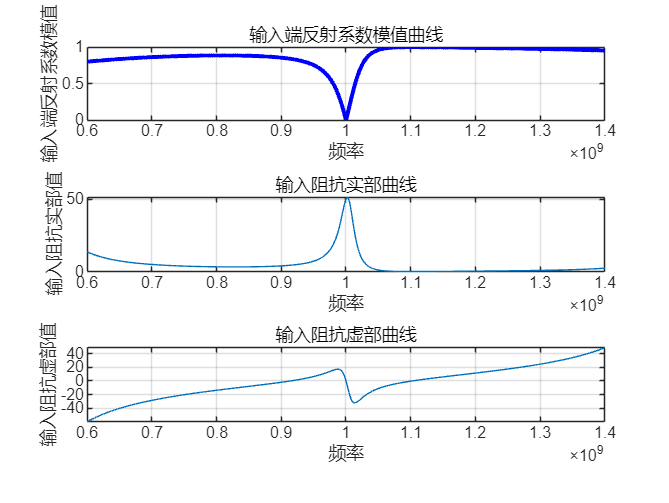

clear;

%----参数设置-----%
Z0=50;                         
Rl=10;                          
Ll=1e-8;                        
fmin=6e8;                       
fstep=1e6;                      
fmax=1.4e9;                     
f0=(fmin+fmax)/2;              
f=fmin:fstep:fmax;              
Zl0=Rl+1i*2*pi*f0*Ll;          
Zl=Rl+1i*2*pi*f*Ll;             

%----实验内容1----%
%使用中心频率的负载计算长度来设计%
[L1_1,L2_1,L1_2,L2_2]=parallel_single(Z0,Zl0);

%----实验内容2----%
        %----解一----%
thata1_1=2*pi*f/f0*L1_1;                
thata2_1=2*pi*f/f0*L2_1;
Zin1_1=input_impedance(Z0,thata1_1,Zl); 
Zin2_1=input_impedance(Z0,thata2_1,0);  
Zin1=parallel_impedance(Zin1_1,Zin2_1); 
T1=(Zin1-Z0)./(Zin1 +Z0);               
figure(1);
subplot(3,1,1)
plot(f,abs(T1),'b','LineWidth', 2)             %反射系数曲线模值频率特性
title('输入端反射系数模值曲线');
xlabel('频率');
ylabel('输入端反射系数模值');
grid on;
subplot(3,1,2)
plot(f,real(Zin1))                %输入阻抗实部频率特性
title('输入阻抗实部曲线');
xlabel('频率');
ylabel('输入阻抗实部值');
grid on;
subplot(3,1,3)                      %输入阻抗虚部频率特性
plot(f,imag(Zin1)) 
title('输入阻抗虚部曲线');
xlabel('频率');
ylabel('输入阻抗虚部值');
grid on;

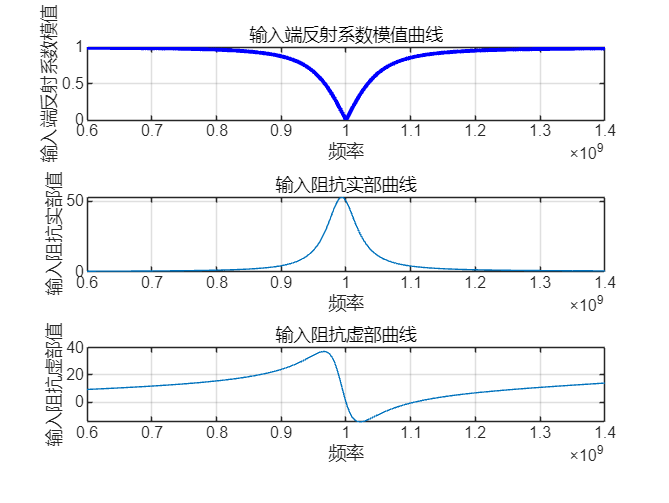




        %----解二----%
thata1_2=2*pi*f/f0*L1_2;
thata2_2=2*pi*f/f0*L2_2;
Zin1_2=input_impedance(Z0,thata1_2,Zl);
Zin2_2=input_impedance(Z0,thata2_2,0);
Zin2=parallel_impedance(Zin1_2,Zin2_2);
T2=(Zin2-Z0)./(Zin2+Z0);
figure(2);
subplot(3,1,1)
plot(f,abs(T2),'b','LineWidth', 2)             %反射系数曲线模值频率特性
title('输入端反射系数模值曲线');
xlabel('频率');
ylabel('输入端反射系数模值');
grid on;
subplot(3,1,2)
plot(f,real(Zin2))                %输入阻抗实部频率特性
title('输入阻抗实部曲线');
xlabel('频率');
ylabel('输入阻抗实部值');
grid on;
subplot(3,1,3)                      %输入阻抗虚部频率特性
plot(f,imag(Zin2)) 
title('输入阻抗虚部曲线');
xlabel('频率');
ylabel('输入阻抗虚部值');
grid on;




function [L1_1,L2_1,L1_2,L2_2]=parallel_single(Z0,Zl0)
    T=(Zl0-Z0)/(Zl0+Z0);            
    p=(1+abs(T))/(1-abs(T));        
    fai=angle(T);                   
    
    Lmin=1/(4*pi)*fai+0.25;         
    %解一
    L1_1p=1/(2*pi)*atan(1/sqrt(p)); 
    L1_1=L1_1p+Lmin;
    L2_1=0.25-1/(2*pi)*atan((1-p)/sqrt(p));
    %解二
    L1_2p=-L1_1p;
    L1_2=L1_2p+Lmin;
    L2_2=0.25+1/(2*pi)*atan((1-p)/sqrt(p));
end

function Zin=input_impedance(Z0,thata,Zl)
Zin=Z0.*(Zl+1i*Z0.*tan(thata))./(Z0+1i*Zl.*tan(thata));
end

function Z=parallel_impedance(Z1,Z2)
Z=(Z1.*Z2)./(Z1+Z2);
end